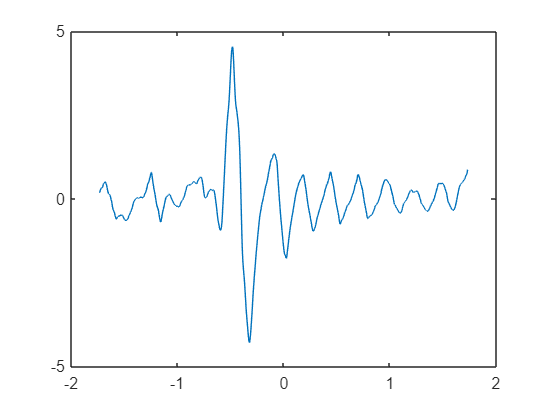

clearvars
dat = readtable('dat.csv','NumHeaderLines',4);  % skips the first three rows of data
dat = dat(1:10000,:); %trims the data to a more reasonable size
windowSize = 5; %defines the size of the window that is captured in each part of the table
dat = normalize(dat);
plot(dat.Var1, dat.Var2);

datLen = length(dat.Var1);
datArray = {};
width = length(dat.Var2)-windowSize;
for i=1:(length(dat.Var2)-windowSize)
    holder = dat(i:(i+windowSize),"Var2");
    datArray = [datArray; holder];
end
datArray = datArray{:,:};
datArray = reshape(datArray, windowSize+1,width);
datArray = transpose(datArray);
inputs = datArray(:,1:windowSize);
outputs = datArray(:,windowSize+1);
inputs = inputs';
outputs = outputs';

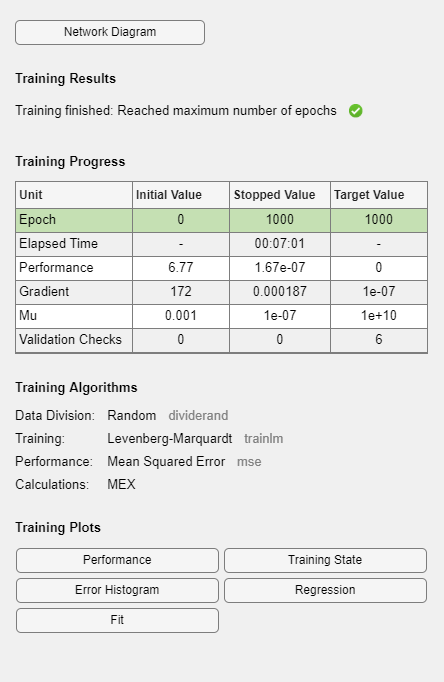

net =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 6
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 511
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1; 1; 1; 1]
      

tr = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'dividerand'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1 2 3 4 5 8 9 10 11 12 15 18 21 23 24 25 26 27 28 32 33 36 37 38 39 40 41 44 46 50 51 52 56 57 58 60 61 65 66 67 68 69 70 72 75 76 77 79 80 81 82 86 87 88 89 90 92 93 94 95 96 97 98 99 100 101 104 106 107 108 109 110 111 112 113 … ]
          valInd: [6 7 13 14 16 17 19 20 22 29 30 31 34 35 42 43 45 47 48 49 53 54 55 59 62 63 64 71 73 74 78 83 84 85 91 102 103 105 117 118 120 127 130 133 134 135 138 142 147 150 158 159 163 164 167 168 169 176 178 192 195 197 203 204 205 206 212 … ]
         testInd: [1×0 double]
            stop: 'Training finished: Reached maximum number of epochs'
      num_epochs: 1000
       trainMask: {[1 1 1 1 1 NaN NaN 1 1 1 1 1 NaN NaN 1 NaN NaN 1 NaN NaN 1 NaN 1 1 1 1 1 1 NaN NaN NaN 1

hiddenSize = [10 10 10 10 10];
net = fitnet(hiddenSize);
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 30/100;
net.divideParam.testRatio = 0/100;
[net, tr] = train(net,inputs,outputs)

yTrain = net(inputs(:,tr.trainInd));
yTrainTrue = outputs(tr.trainInd)

yTrainTrue =     0.1987    0.2028    0.2073    0.2120    0.2169    0.2300    0.2330    0.2358    0.2388    0.2427    0.2542    0.2628    0.2688    0.2718    0.2733    0.2746    0.2765    0.2785    0.2804    0.2900    0.2928    0.3040    0.3081    0.3119    0.3145    0.3162    0.3173    0.3205    0.3239    0.3304    0.3304    0.3302    0.3278    0.3271    0.3274    0.3276    0.3269    0.3241    0.3250    0.3263    0.3286    0.3308    0.3329    0.3351    0.3372    0.3389    0.3417    0.3492    0.3537    0.3585


RMSE = sqrt(mean((yTrain-yTrainTrue).^2))

RMSE = 4.0828e-04

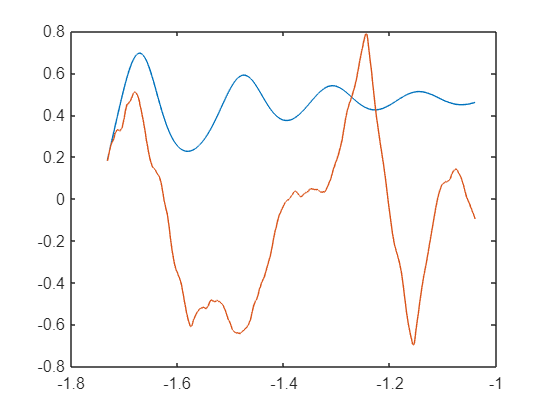


lookAhead = 2000;
predictions = zeros(1,lookAhead);
predictions(1:windowSize) = inputs(:,2);
for i=6:lookAhead%length(tr.trainInd)
    wBelow = (i-windowSize);
    n = predictions(1,wBelow:i-1)';
    stepAhead = net(n);
    predictions(i) = stepAhead;
end
plot(dat.Var1(1:lookAhead),predictions)
hold on
plot(dat.Var1(1:lookAhead),dat.Var2(1:lookAhead))
hold off

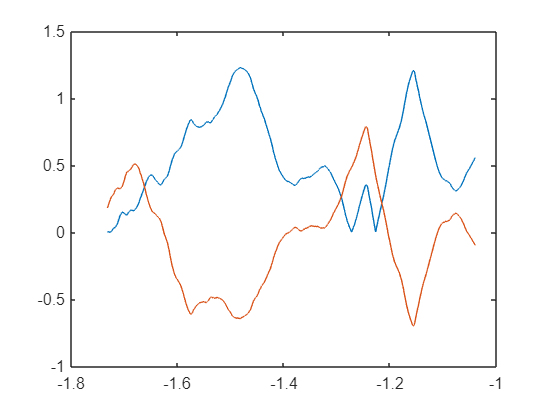

differences = zeros(1,i);
for i=1:length(predictions)
    differences(i) = abs(predictions(i)-dat.Var2(i));
end
plot(dat.Var1(1:i),differences);
hold on
plot(dat.Var1(1:i),dat.Var2(1:i));